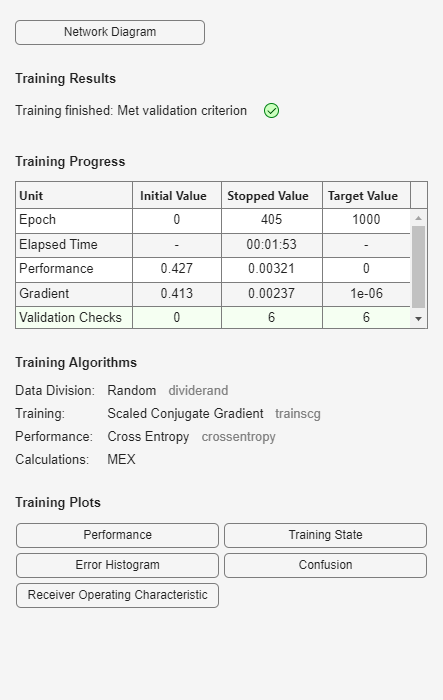

% =========================
% Read dataset
% =========================
tbl = readtable("ANN_dataset.csv");

% Extract inputs and targets
inputs = tbl{:, 1:end-1}';       % features × samples (now 9 features: Id, Iq, Id_ref, Iq_ref, Te, We, theta, sin, cos)
targets_raw = tbl{:, end};       % categorical outputs (0–7)

% Shift labels to start from 1 (required for MATLAB one-hot encoding)
targets_shifted = targets_raw + 1;

% Number of classes
numClasses = numel(unique(targets_shifted));

% Manual one-hot encoding
N = length(targets_shifted);
targets = zeros(numClasses, N);
for i = 1:N
    targets(targets_shifted(i), i) = 1;
end

% =========================
% Define a 2-hidden-layer classification neural network
% =========================
hiddenLayerSize = [50 30];   % two layers: 50 neurons, then 30 neurons
net = patternnet(hiddenLayerSize);

% Split data
net.divideParam.trainRatio = 0.7;
net.divideParam.valRatio = 0.15;
net.divideParam.testRatio = 0.15;

% =========================
% Train the network
% =========================
[net, tr] = train(net, inputs, targets);


% =========================
% Test the network
% =========================
outputs = net(inputs);
[~, predicted] = max(outputs);       % predicted classes (1–numClasses)
[~, actual] = max(targets);          % true classes (1–numClasses)

% Convert back to original labels (0–7)
predicted = predicted - 1;
actual = actual - 1;

% Accuracy
accuracy = sum(predicted == actual) / numel(actual) * 100;
fprintf("Classification Accuracy: %.2f%%\n", accuracy);

Classification Accuracy: 99.45%



% Numeric confusion matrix
confMat = confusionmat(actual, predicted);
disp('Confusion Matrix:');

Confusion Matrix:


disp(confMat);

       16550           6          53           4          27           2
           1       16608          56           2           3          41
          43          76       16578           4           0           2
           1           0           4       16378          29          39
          39           6           1          32       16744           1
           0          40           4          35           2       16590



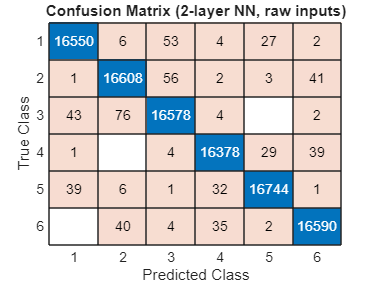


% Confusion chart
figure;
confusionchart(confMat);
title('Confusion Matrix (2-layer NN, raw inputs)');

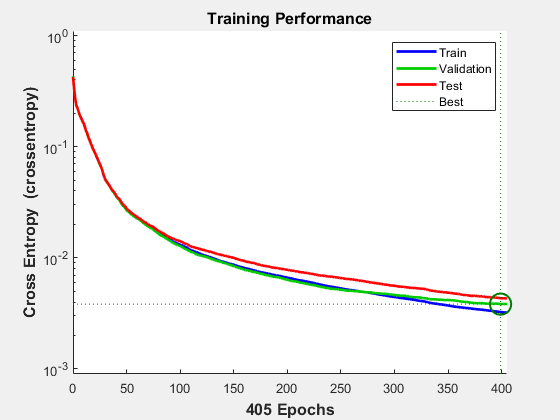


% Training performance
figure;
plotperform(tr);
title('Training Performance');


% =========================
% Save the trained network
% =========================
save('trainedANN.mat','net');
